# **Question 2**				

For a control input $u\left(t\right)$ to the motor, the platform angle changes continuously according to:


$$\;\theta^˙ \left(t\right)=K_m \left(u\left(t\right)-\theta \left(t\right)\right)$$


The continuous open loop transfer function is:


$$\frac{D}{U}=\frac{K_m \textrm{mg}}{s\left(s+K_m \right)\left(\textrm{ms}+b\right)}=\frac{K_m \textrm{mg}}{{\textrm{ms}}^3 +\left(b+K_m m\right)s^2 +K_m \textrm{bs}}$$


m = 10;
b = 1.5;
g = 9.8;
K_m = 25;

sys = tf([K_m*m*g],[m, (b + K_m*m), K_m*b, 0])


sys =
 
             2450
  ---------------------------
  10 s^3 + 251.5 s^2 + 37.5 s
 
Continuous-time transfer function.



## **2b)**

P controller:

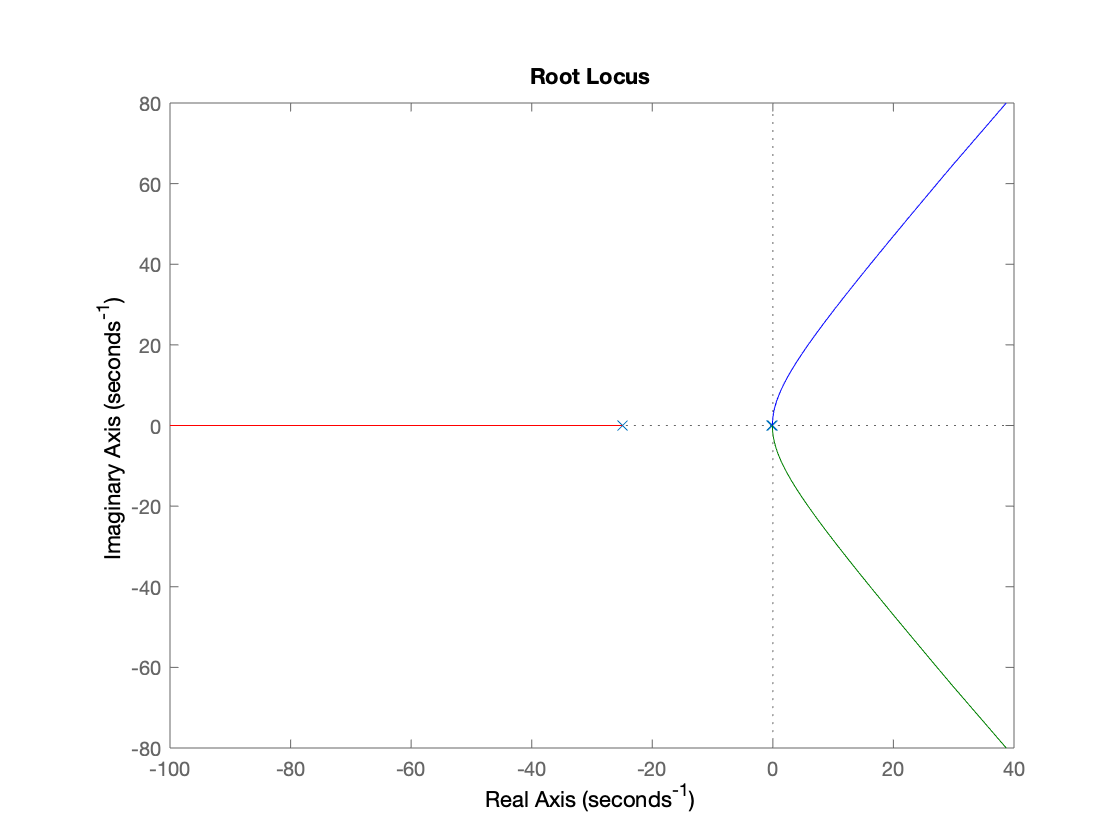

rlocus(sys)

PD controller:

PD = tf([1,1],[1])


PD =
 
  s + 1
 
Continuous-time transfer function.



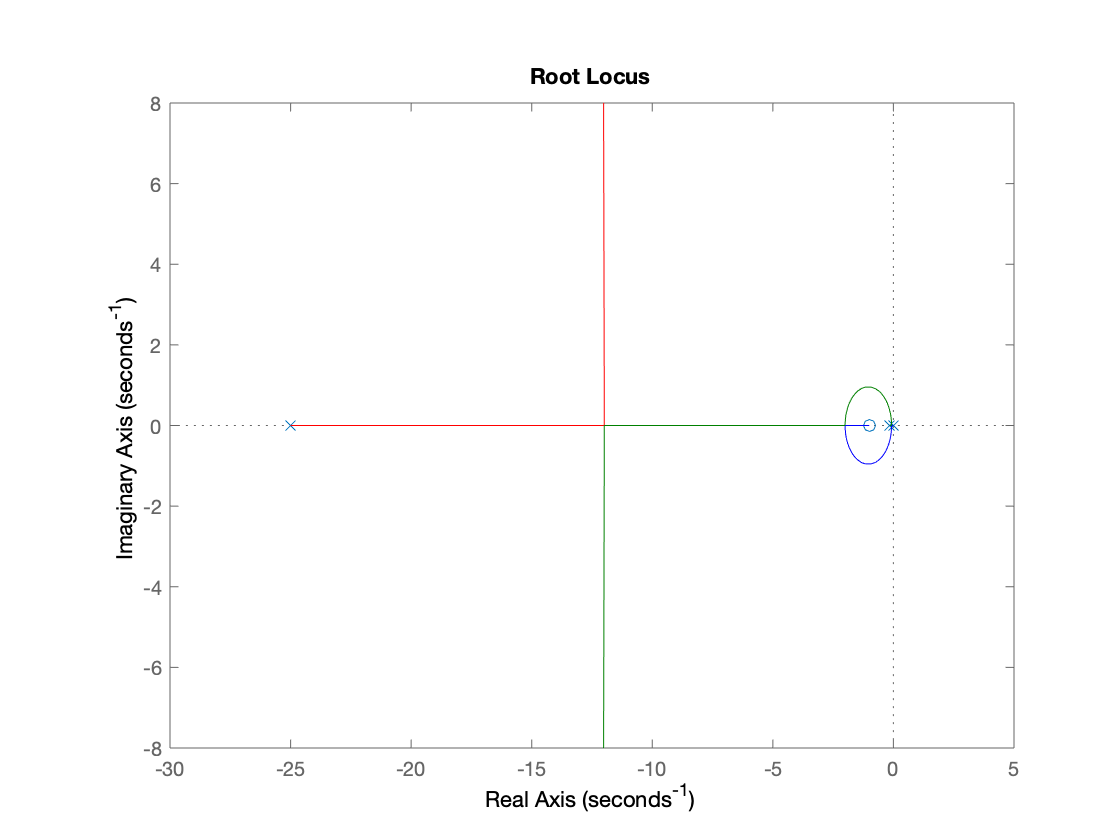

rlocus(PD*sys)

PI controller:

PI = tf([1,1],[1,0])


PI =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



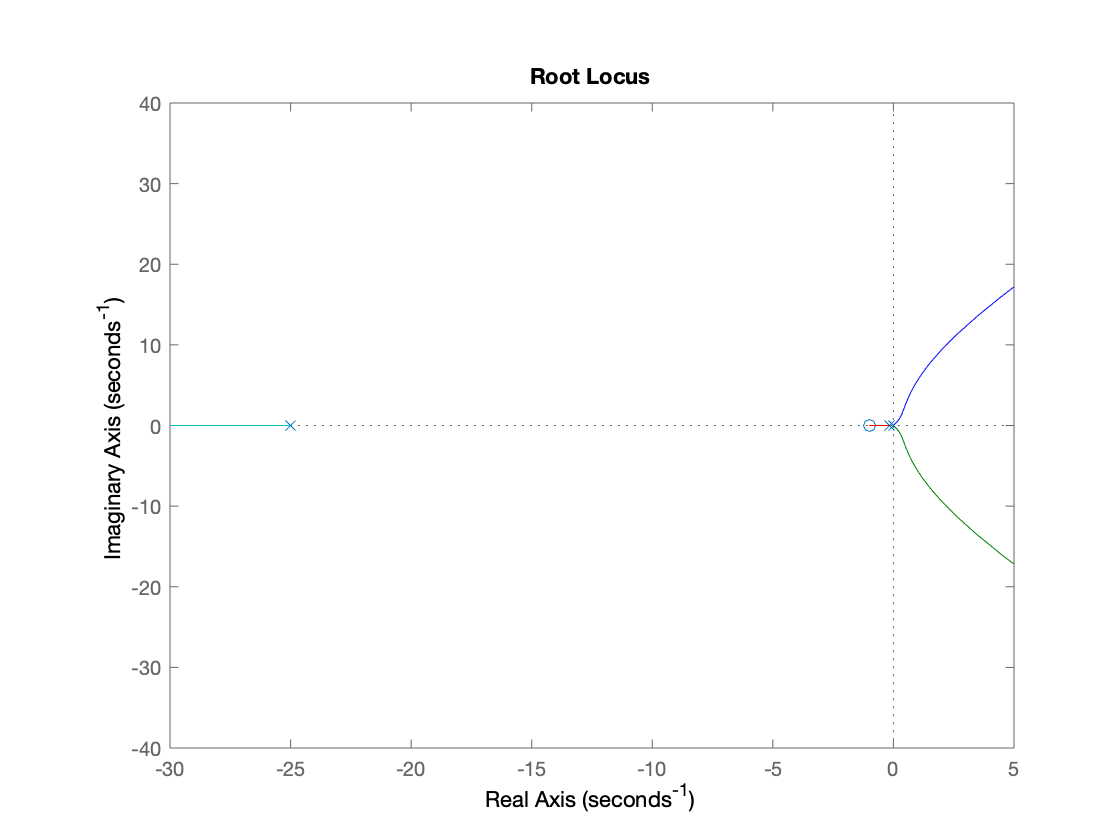

rlocus(PI*sys)
xlim([-30, 5])

## **Q2c)**

The gain for the PD conpensated system that can produce a phase margin around 76 ~ 78 degrees is 0.00063306 (77.3 degree).

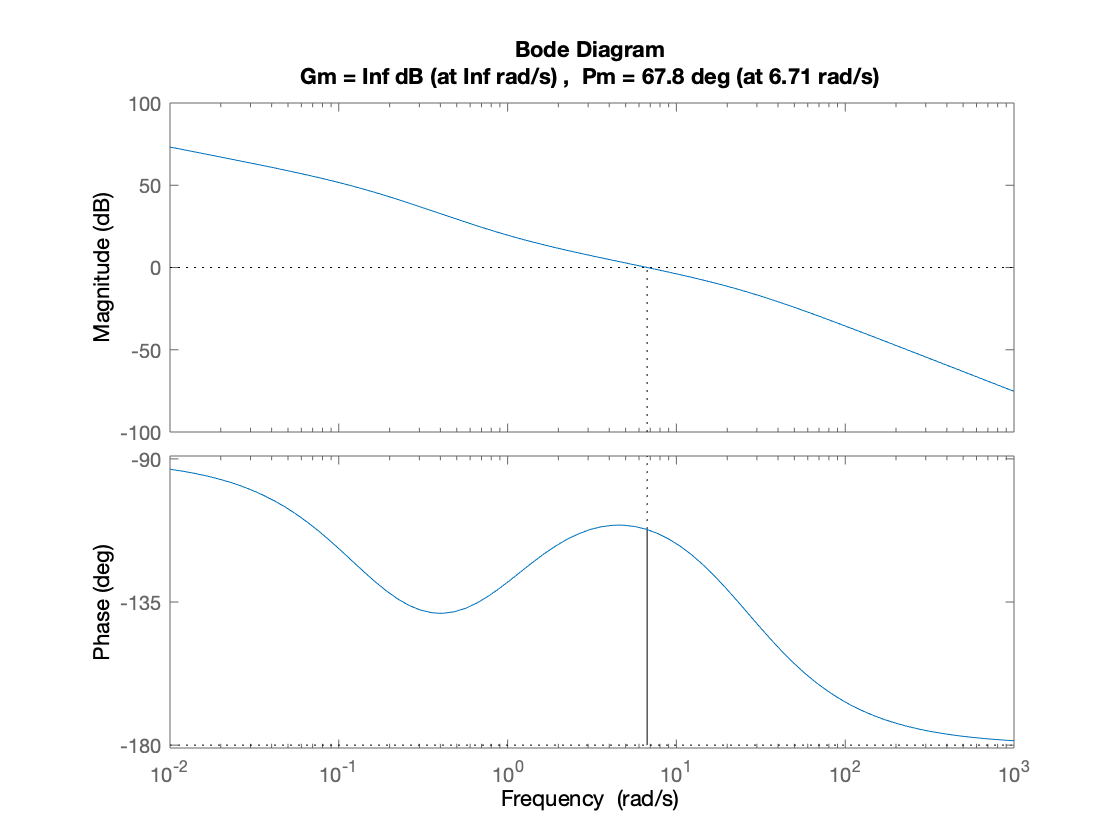

margin(0.70172*PD*sys)

Discretise the transfer function of this controller with a sampling time of 0.1 seconds.

D_PD_controller = c2d(0.70172*PD, 0.1, 'tustin')


D_PD_controller =
 
  14.74 z - 13.33
  ---------------
       z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



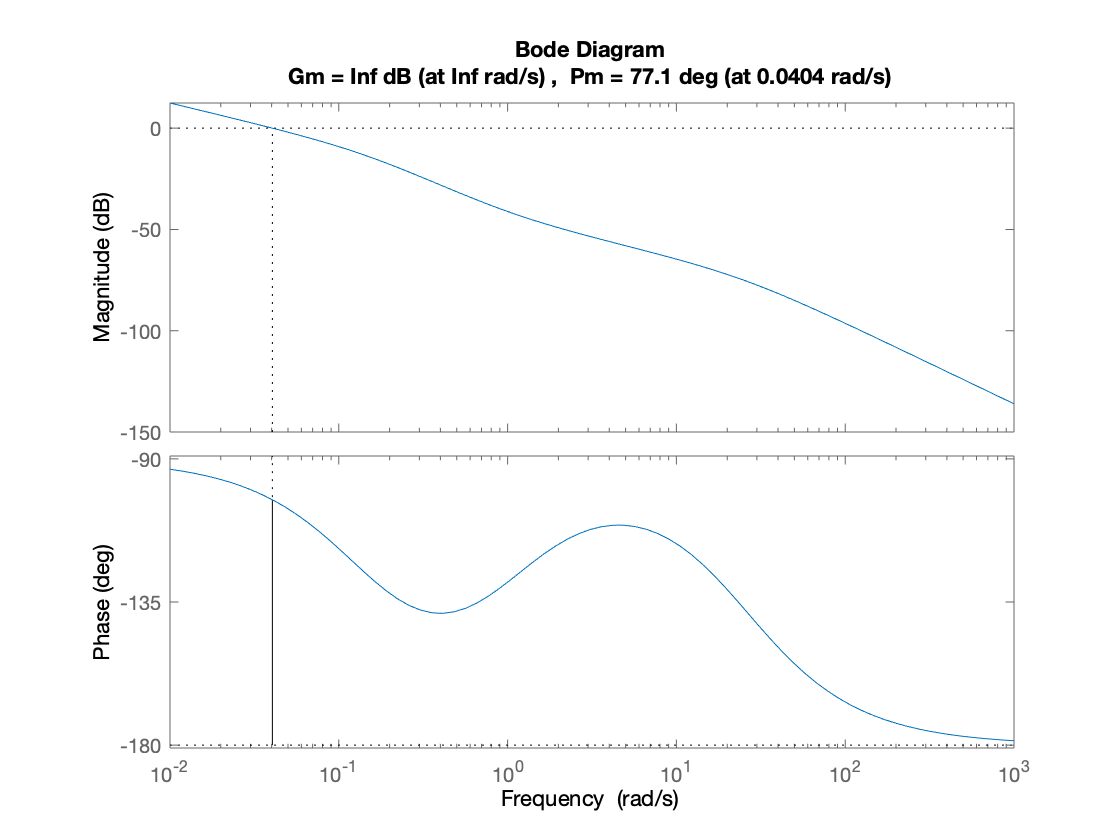

margin(0.00064008*PD*sys)

c2d(0.00064008*PD, 0.1, 'tustin')


ans =
 
  0.01344 z - 0.01216
  -------------------
         z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.

